clear;
%% Load Data
folder_path_healthy = 'F:\University of Maryland\Graduate School Reliability Engineering\ENME 691\Project1\Training\Healthy';
folder_path_unbalance1 = 'F:\University of Maryland\Graduate School Reliability Engineering\ENME 691\Homework\HW3\Training\Faulty\Unbalance 1';
folder_path_unbalance2 = 'F:\University of Maryland\Graduate School Reliability Engineering\ENME 691\Homework\HW3\Training\Faulty\Unbalance 2';
folder_path_testing = 'F:\University of Maryland\Graduate School Reliability Engineering\ENME 691\Project1\Testing\Testing';

all_data_healthy = loadDataFromFolder(folder_path_healthy);
all_data_unbalance1 = loadDataFromFolder(folder_path_unbalance1);
all_data_unbalance2 = loadDataFromFolder(folder_path_unbalance2);

%% Extract Time Domain and First Harmonic Features

% Initialize feature vectors for healthy data
rms_values_healthy = zeros(length(all_data_healthy), 1);
mean_values_healthy = zeros(length(all_data_healthy), 1);
peak_to_peak_values_healthy = zeros(length(all_data_healthy), 1);
std_values_healthy = zeros(length(all_data_healthy), 1);
skewness_values_healthy = zeros(length(all_data_healthy), 1);
kurtosis_values_healthy = zeros(length(all_data_healthy), 1);
first_harmonic_values_healthy = zeros(length(all_data_healthy), 1); % First harmonic

% Initialize feature vectors for Unbalance 1 data
rms_values_unbalance1 = zeros(length(all_data_unbalance1), 1);
mean_values_unbalance1 = zeros(length(all_data_unbalance1), 1);
peak_to_peak_values_unbalance1 = zeros(length(all_data_unbalance1), 1);
std_values_unbalance1 = zeros(length(all_data_unbalance1), 1);
skewness_values_unbalance1 = zeros(length(all_data_unbalance1), 1);
kurtosis_values_unbalance1 = zeros(length(all_data_unbalance1), 1);
first_harmonic_values_unbalance1 = zeros(length(all_data_unbalance1), 1); % First harmonic

% Initialize feature vectors for Unbalance 2 data
rms_values_unbalance2 = zeros(length(all_data_unbalance2), 1);
mean_values_unbalance2 = zeros(length(all_data_unbalance2), 1);
peak_to_peak_values_unbalance2 = zeros(length(all_data_unbalance2), 1);
std_values_unbalance2 = zeros(length(all_data_unbalance2), 1);
skewness_values_unbalance2 = zeros(length(all_data_unbalance2), 1);
kurtosis_values_unbalance2 = zeros(length(all_data_unbalance2), 1);
first_harmonic_values_unbalance2 = zeros(length(all_data_unbalance2), 1); % First harmonic

% Extract features for healthy data
for i = 1:length(all_data_healthy)
    data = all_data_healthy{i}.data;
    
    % Calculate Time Domain Features
    rms_values_healthy(i) = rms(data);
    mean_values_healthy(i) = mean(data);
    peak_to_peak_values_healthy(i) = max(data) - min(data);
    std_values_healthy(i) = std(data);
    skewness_values_healthy(i) = skewness(data);
    kurtosis_values_healthy(i) = kurtosis(data);
    
    % Calculate First Harmonic from Frequency Domain
    first_harmonic_values_healthy(i) = calculateFirstHarmonic(data);
end

% Extract features for Unbalance 1 data
for i = 1:length(all_data_unbalance1)
    data = all_data_unbalance1{i}.data;
    
    % Calculate Time Domain Features
    rms_values_unbalance1(i) = rms(data);
    mean_values_unbalance1(i) = mean(data);
    peak_to_peak_values_unbalance1(i) = max(data) - min(data);
    std_values_unbalance1(i) = std(data);
    skewness_values_unbalance1(i) = skewness(data);
    kurtosis_values_unbalance1(i) = kurtosis(data);
    
    % Calculate First Harmonic from Frequency Domain
    first_harmonic_values_unbalance1(i) = calculateFirstHarmonic(data);
end

% Extract features for Unbalance 2 data
for i = 1:length(all_data_unbalance2)
    data = all_data_unbalance2{i}.data;
    
    % Calculate Time Domain Features
    rms_values_unbalance2(i) = rms(data);
    mean_values_unbalance2(i) = mean(data);
    peak_to_peak_values_unbalance2(i) = max(data) - min(data);
    std_values_unbalance2(i) = std(data);
    skewness_values_unbalance2(i) = skewness(data);
    kurtosis_values_unbalance2(i) = kurtosis(data);
    
    % Calculate First Harmonic from Frequency Domain
    first_harmonic_values_unbalance2(i) = calculateFirstHarmonic(data);
end

%% Combine Features and Labels

% Combine feature vectors
features_healthy = [rms_values_healthy, mean_values_healthy, peak_to_peak_values_healthy, std_values_healthy, skewness_values_healthy, kurtosis_values_healthy, first_harmonic_values_healthy];
features_unbalance1 = [rms_values_unbalance1, mean_values_unbalance1, peak_to_peak_values_unbalance1, std_values_unbalance1, skewness_values_unbalance1, kurtosis_values_unbalance1, first_harmonic_values_unbalance1];
features_unbalance2 = [rms_values_unbalance2, mean_values_unbalance2, peak_to_peak_values_unbalance2, std_values_unbalance2, skewness_values_unbalance2, kurtosis_values_unbalance2, first_harmonic_values_unbalance2];

% Combine labels
labels_healthy = zeros(length(all_data_healthy), 1); % Label 0 for healthy
labels_unbalance1 = ones(length(all_data_unbalance1), 1); % Label 1 for Unbalance 1
labels_unbalance2 = 2 * ones(length(all_data_unbalance2), 1); % Label 2 for Unbalance 2

% Combine features and labels
X = [features_healthy; features_unbalance1; features_unbalance2];
y = [labels_healthy; labels_unbalance1; labels_unbalance2];



%% Train Multi-Class SVM Model (Using Error Correcting Output Codes - ECOC)

% Define different kernels
kernels = {'linear', 'polynomial', 'gaussian', 'rbf'};

% Initialize a matrix to store accuracies for each kernel
kernelAccuracies = zeros(length(kernels), 1);

for kIndex = 1:length(kernels)
    % Set up the SVM template for current kernel
    t = templateSVM('KernelFunction', kernels{kIndex}, 'Standardize', true);

    % Train the SVM model using ECOC
    SVMModel = fitcecoc(X, y, 'Learners', t);

    % Predict the labels using the trained model
    predicted_labels = predict(SVMModel, X);

    % Calculate and store the accuracy
    accuracy = sum(predicted_labels == y) / numel(y);
    kernelAccuracies(kIndex) = accuracy;

    % Display the accuracy for the current kernel
    fprintf('Accuracy with %s kernel: %.2f%%\n', kernels{kIndex}, accuracy * 100);
end

Accuracy with linear kernel: 98.33%
Accuracy with polynomial kernel: 100.00%
Accuracy with gaussian kernel: 100.00%
Accuracy with rbf kernel: 100.00%



% Find the best performing kernel
[bestAccuracy, bestIndex] = max(kernelAccuracies);
fprintf('\nBest performing kernel: %s with an accuracy of %.2f%%\n', kernels{bestIndex}, bestAccuracy * 100);


Best performing kernel: polynomial with an accuracy of 100.00%



bestKernel = kernels{bestIndex}; % Get the best kernel

% Set up the SVM template for the best kernel
t_best = templateSVM('KernelFunction', bestKernel, 'Standardize', true);

% Train the SVM model using the best kernel
SVMModel = fitcecoc(X, y, 'Learners', t_best);



%% Load test data from folder
all_data_testing = loadDataFromFolder(folder_path_testing);

% Initialize feature vectors for test data
rms_values_testing = zeros(length(all_data_testing), 1);
mean_values_testing = zeros(length(all_data_testing), 1);
peak_to_peak_values_testing = zeros(length(all_data_testing), 1);
std_values_testing = zeros(length(all_data_testing), 1);
skewness_values_testing = zeros(length(all_data_testing), 1);
kurtosis_values_testing = zeros(length(all_data_testing), 1);
first_harmonic_values_testing = zeros(length(all_data_testing), 1); % First harmonic for test data

% Extract features for test data
for i = 1:length(all_data_testing)
    data = all_data_testing{i}.data;
    
    % Calculate Time Domain Features
    rms_values_testing(i) = rms(data);
    mean_values_testing(i) = mean(data);
    peak_to_peak_values_testing(i) = max(data) - min(data);
    std_values_testing(i) = std(data);
    skewness_values_testing(i) = skewness(data);
    kurtosis_values_testing(i) = kurtosis(data);
    
    % Calculate First Harmonic from Frequency Domain
    first_harmonic_values_testing(i) = calculateFirstHarmonic(data);
end

% Combine features for test data
features_testing = [rms_values_testing, mean_values_testing, peak_to_peak_values_testing, std_values_testing, skewness_values_testing, kurtosis_values_testing, first_harmonic_values_testing];

% Predict labels for the test data using the trained SVM model
predicted_labels_testing = predict(SVMModel, features_testing);
filenames_testing = cell(length(all_data_testing), 1);
class_labels = {'Healthy', 'Unbalance 1', 'Unbalance 2'};

% Predict the labels for the test data using the trained model
predicted_labels_testing_best = predict(SVMModel, features_testing);

% Display the filenames along with predicted labels for the test data
disp('Filenames and Predicted Labels (Best Kernel):');

Filenames and Predicted Labels (Best Kernel):


for i = 1:length(predicted_labels_testing_best)
    fprintf('%s: Predicted Label - %s\n', filenames_testing{i}, class_labels{predicted_labels_testing_best(i) + 1});
end

: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 2
: Predicted Label - Unbalance 2
: Predicted Label - Unbalance 2
: Predicted Label - Unbalance 2
: Predicted Label - Unbalance 2
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 2
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1




% Count the occurrences of each predicted class
class_counts = histcounts(predicted_labels_testing, 'BinMethod', 'integers');

% Define class labels

% Display the class counts with labels
disp('Class Counts for Predicted Labels on Test Data:');

Class Counts for Predicted Labels on Test Data:


for i = 1:length(class_labels)
    fprintf('%s: %d\n', class_labels{i}, class_counts(i));
end

Healthy: 10
Unbalance 1: 14
Unbalance 2: 6



% Display filenames along with predicted labels
disp('Filenames and Predicted Labels:');

Filenames and Predicted Labels:


for i = 1:length(predicted_labels_testing)
    fprintf('%s: Predicted Label - %s\n', filenames_testing{i}, class_labels{predicted_labels_testing(i) + 1});
end

: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Healthy
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 2
: Predicted Label - Unbalance 2
: Predicted Label - Unbalance 2
: Predicted Label - Unbalance 2
: Predicted Label - Unbalance 2
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 2
: Predicted Label - Unbalance 1
: Predicted Label - Unbalance 1


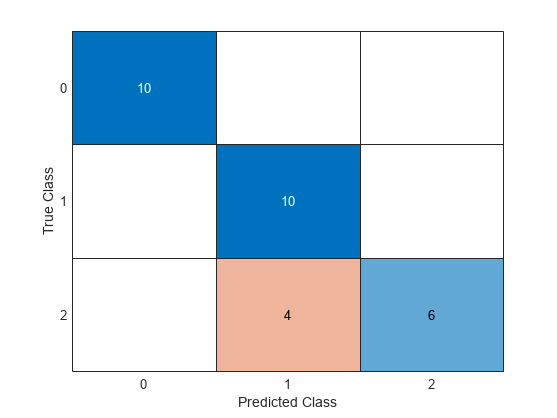

% Define True Labels based on the image provided
true_labels = [zeros(10, 1); ones(10, 1); 2*ones(10, 1)]; % 0 for Healthy, 1 for Unbalance Level 1, 2 for Unbalance Level 2

% Generate Confusion Matrix
confMatrix = confusionchart(true_labels, predicted_labels_testing);


% Display the Confusion Matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMatrix);

  ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 double]

  Show all properties




% Calculate and Display Overall Accuracy
correct_predictions = sum(confMatrix.NormalizedValues(logical(eye(size(confMatrix.NormalizedValues))))); % Sum of correct predictions (diagonal elements)
total_predictions = sum(confMatrix.NormalizedValues, 'all'); % Total number of predictions
overallAccuracy = correct_predictions / total_predictions * 100; % Calculate overall accuracy
fprintf('Overall Accuracy: %.2f%%\n', overallAccuracy);

Overall Accuracy: 86.67%




% Calculate and Display Precision, Recall, and F1-Score for Each Class
for i = 1:size(confMatrix.NormalizedValues, 1)
    % Precision
    precision = confMatrix.NormalizedValues(i, i) / sum(confMatrix.NormalizedValues(:, i));
    
    % Recall
    recall = confMatrix.NormalizedValues(i, i) / sum(confMatrix.NormalizedValues(i, :));
    
    % F1-score
    f1Score = 2 * (precision * recall) / (precision + recall);
    
    fprintf('Class %d - Precision: %.4f, Recall: %.4f, F1 Score: %.4f\n', i-1, precision, recall, f1Score);
end

Class 0 - Precision: 1.0000, Recall: 1.0000, F1 Score: 1.0000
Class 1 - Precision: 0.7143, Recall: 1.0000, F1 Score: 0.8333
Class 2 - Precision: 1.0000, Recall: 0.6000, F1 Score: 0.7500


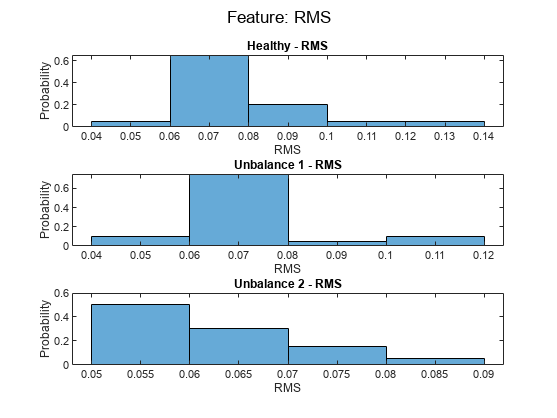

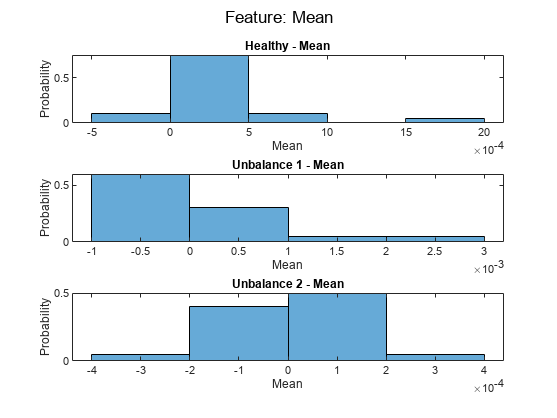

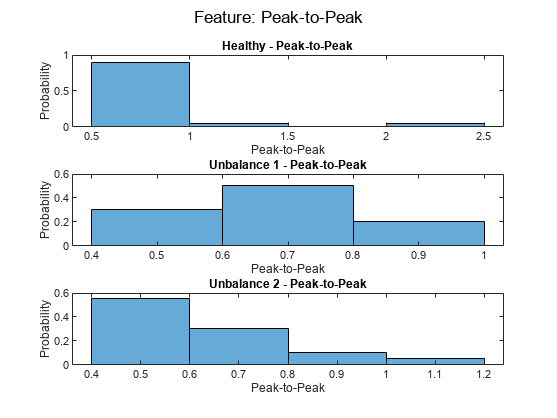

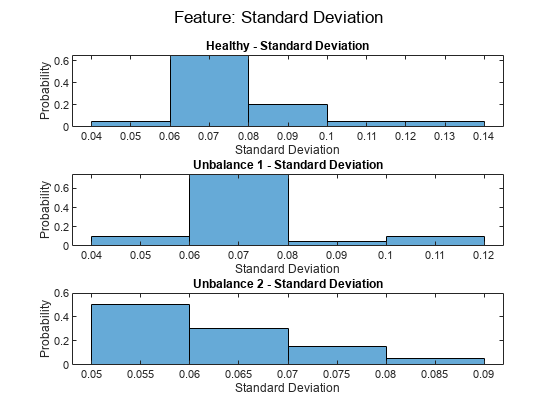

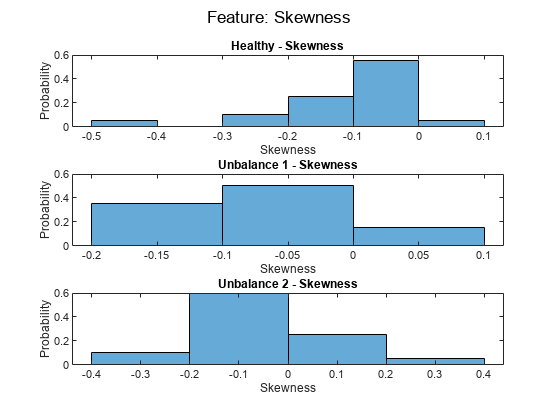

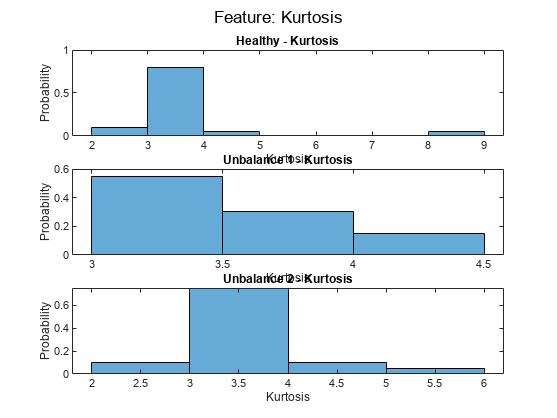

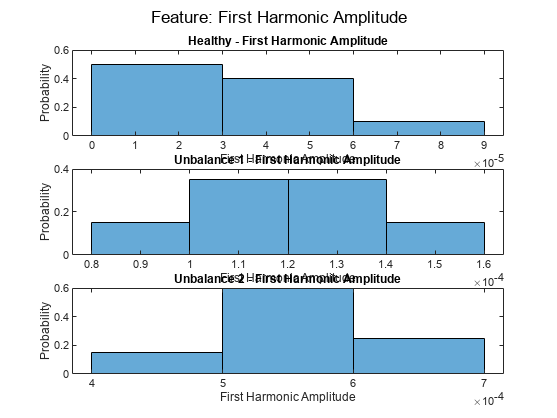


%% Plot Time Domain Features for Each Class Separately

% Define feature names
feature_names = {'RMS', 'Mean', 'Peak-to-Peak', 'Standard Deviation', 'Skewness', 'Kurtosis', 'First Harmonic Amplitude'};

% Iterate over each feature
for featureIndex = 1:length(feature_names)
    % Create a new figure for each feature
    figure;
    
    % Plot healthy data
    subplot(3, 1, 1);
    histogram(X(y == 0, featureIndex), 'Normalization', 'probability');
    title(['Healthy - ' feature_names{featureIndex}]);
    xlabel(feature_names{featureIndex});
    ylabel('Probability');
    
    % Plot Unbalance 1 data
    subplot(3, 1, 2);
    histogram(X(y == 1, featureIndex), 'Normalization', 'probability');
    title(['Unbalance 1 - ' feature_names{featureIndex}]);
    xlabel(feature_names{featureIndex});
    ylabel('Probability');
    
    % Plot Unbalance 2 data
    subplot(3, 1, 3);
    histogram(X(y == 2, featureIndex), 'Normalization', 'probability');
    title(['Unbalance 2 - ' feature_names{featureIndex}]);
    xlabel(feature_names{featureIndex});
    ylabel('Probability');
    
    % Adjust the layout
    sgtitle(['Feature: ' feature_names{featureIndex}]);
end

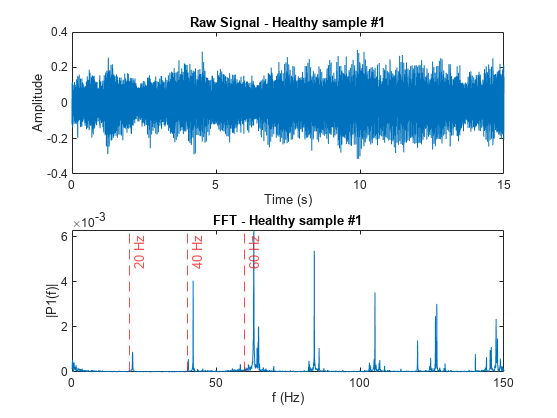


% Example usage
Fs = 2560; % Sampling frequency
data_healthy = all_data_healthy{1}.data; % Assuming your data is stored this way
data_unbalanced1 = all_data_unbalance1{1}.data;
data_unbalanced2 = all_data_unbalance2{1}.data;

figure;
plotSampleAndFFT(data_healthy, Fs, 'Healthy sample #1');

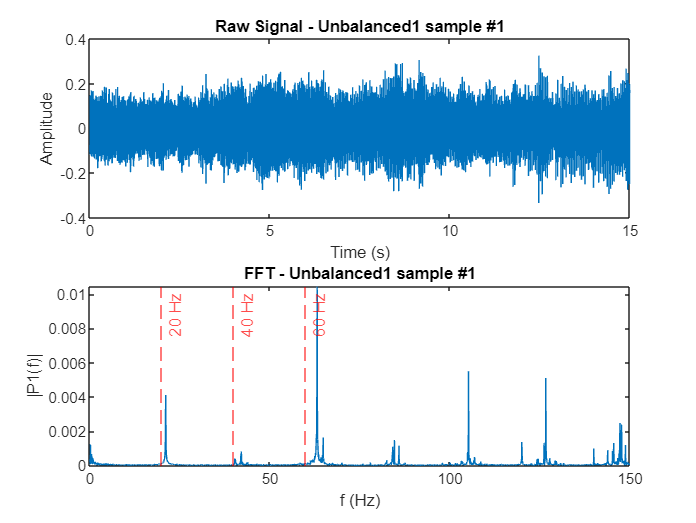


figure;
plotSampleAndFFT(data_unbalanced1, Fs, 'Unbalanced1 sample #1');

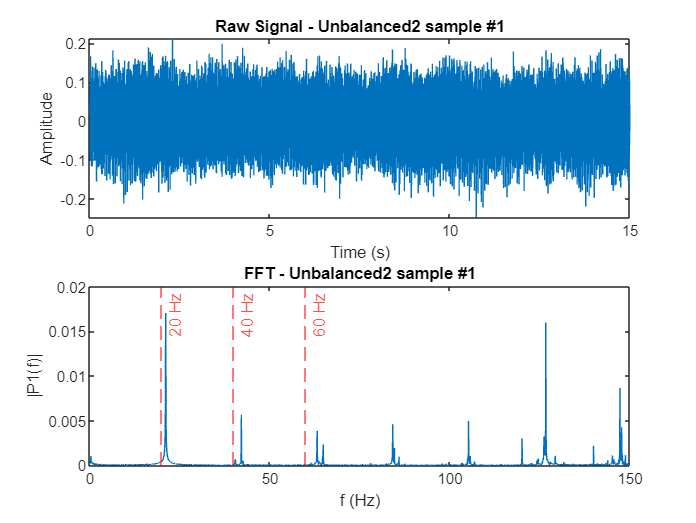


figure;
plotSampleAndFFT(data_unbalanced2, Fs, 'Unbalanced2 sample #1');

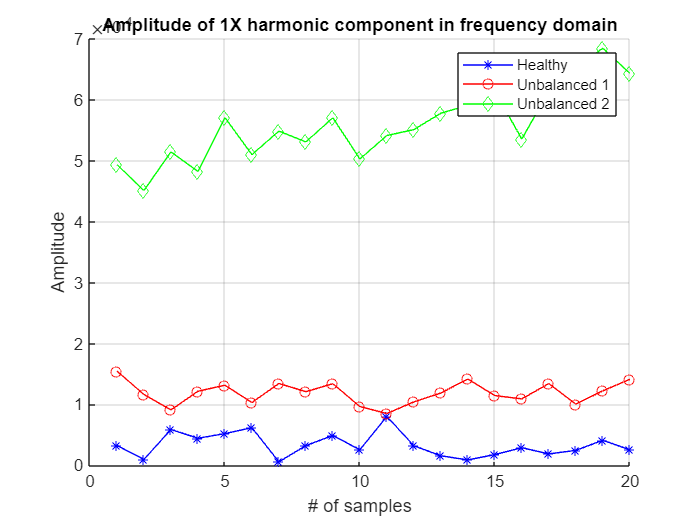

% Sample indices for plotting
samples = 1:20; 

% Plotting the amplitude of 1X harmonic component
figure;
hold on;
plot(samples, first_harmonic_values_healthy(1:20), 'b-*', 'DisplayName', 'Healthy');
plot(samples, first_harmonic_values_unbalance1(1:20), 'r-o', 'DisplayName', 'Unbalanced 1');
plot(samples, first_harmonic_values_unbalance2(1:20), 'g-d', 'DisplayName', 'Unbalanced 2');
hold off;
xlabel('# of samples');
ylabel('Amplitude');
title('Amplitude of 1X harmonic component in frequency domain');
legend('show');
grid on;

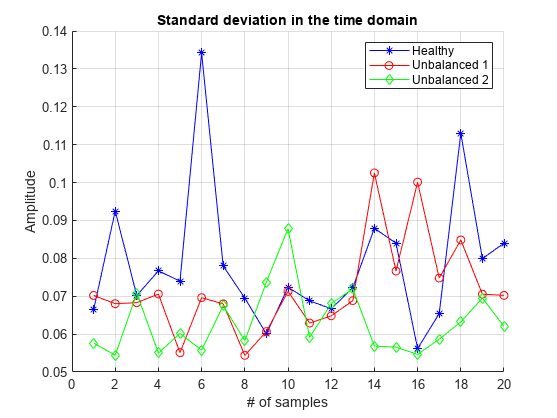


% Plotting the standard deviation in the time domain
figure;
hold on;
plot(samples, std_values_healthy(1:20), 'b-*', 'DisplayName', 'Healthy');
plot(samples, std_values_unbalance1(1:20), 'r-o', 'DisplayName', 'Unbalanced 1');
plot(samples, std_values_unbalance2(1:20), 'g-d', 'DisplayName', 'Unbalanced 2');
hold off;
xlabel('# of samples');
ylabel('Amplitude');
title('Standard deviation in the time domain');
legend('show');
grid on;

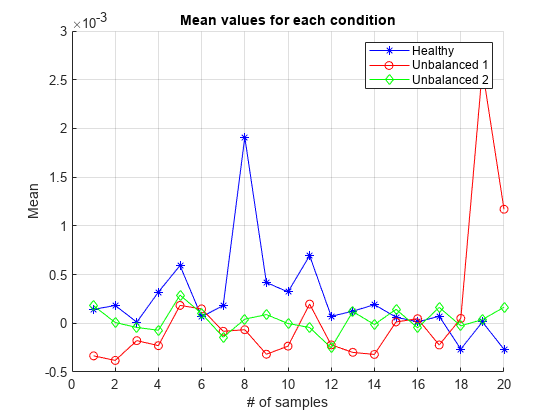

% Plotting the Mean values
figure;
hold on;
plot(samples, mean_values_healthy(1:20), 'b-*', 'DisplayName', 'Healthy');
plot(samples, mean_values_unbalance1(1:20), 'r-o', 'DisplayName', 'Unbalanced 1');
plot(samples, mean_values_unbalance2(1:20), 'g-d', 'DisplayName', 'Unbalanced 2');
hold off;
xlabel('# of samples');
ylabel('Mean');
title('Mean values for each condition');
legend('show');
grid on;

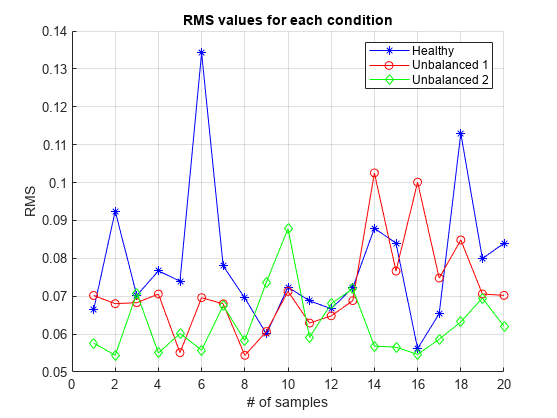


% Plotting the RMS values
figure;
hold on;
plot(samples, rms_values_healthy(1:20), 'b-*', 'DisplayName', 'Healthy');
plot(samples, rms_values_unbalance1(1:20), 'r-o', 'DisplayName', 'Unbalanced 1');
plot(samples, rms_values_unbalance2(1:20), 'g-d', 'DisplayName', 'Unbalanced 2');
hold off;
xlabel('# of samples');
ylabel('RMS');
title('RMS values for each condition');
legend('show');
grid on;

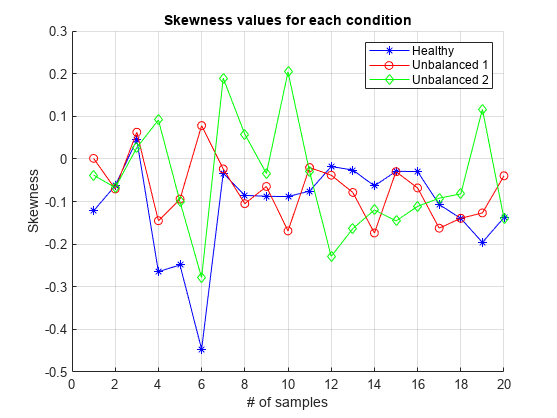


% Plotting the Skewness values
figure;
hold on;
plot(samples, skewness_values_healthy(1:20), 'b-*', 'DisplayName', 'Healthy');
plot(samples, skewness_values_unbalance1(1:20), 'r-o', 'DisplayName', 'Unbalanced 1');
plot(samples, skewness_values_unbalance2(1:20), 'g-d', 'DisplayName', 'Unbalanced 2');
hold off;
xlabel('# of samples');
ylabel('Skewness');
title('Skewness values for each condition');
legend('show');
grid on;

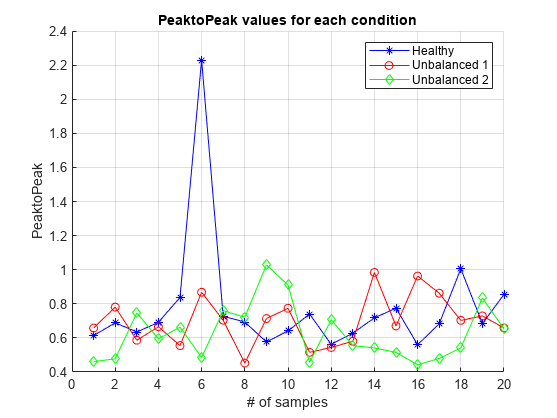


% Plotting the PeaktoPeak values
figure;
hold on;
plot(samples, peak_to_peak_values_healthy(1:20), 'b-*', 'DisplayName', 'Healthy');
plot(samples, peak_to_peak_values_unbalance1(1:20), 'r-o', 'DisplayName', 'Unbalanced 1');
plot(samples, peak_to_peak_values_unbalance2(1:20), 'g-d', 'DisplayName', 'Unbalanced 2');
hold off;
xlabel('# of samples');
ylabel('PeaktoPeak');
title('PeaktoPeak values for each condition');
legend('show');
grid on;

function [all_data] = loadDataFromFolder(folder_path)
    file_list = dir(fullfile(folder_path, '*.txt'));
    all_data = cell(length(file_list), 1);
    for i = 1:length(file_list)
        file_path = fullfile(folder_path, file_list(i).name);
        if endsWith(file_list(i).name, '.txt')
            all_data{i} = importdata(file_path);
        end
    end
end

function [firstHarmonicAmplitude] = calculateFirstHarmonic(data)
    Fs = 2560;
    N = length(data);
    Y = fft(data);
    P2 = abs(Y/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1); % Double-sided spectrum to single-sided spectrum
    f = Fs*(0:(N/2))/N; % Frequency range
    
    target_frequency = 20; % Target frequency for the first harmonic in Hz
    
    % Find the closest frequency bin to the target frequency
    [~, closestIndex] = min(abs(f - target_frequency));
    
    % Amplitude of the closest frequency to the target first harmonic
    firstHarmonicAmplitude = P1(closestIndex);
end
function plotSampleAndFFT(data, Fs, titleText)
    % Time-domain plot
    subplot(2, 1, 1); % 2 rows, 1 column, first subplot
    t = (0:length(data)-1)/Fs; % Time vector
    plot(t, data);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['Raw Signal - ' titleText]);

    % FFT plot
    subplot(2, 1, 2); % 2 rows, 1 column, second subplot
    N = length(data);
    Y = fft(data);
    P2 = abs(Y/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1); % Double-sided spectrum to single-sided spectrum
    f = Fs*(0:(N/2))/N; % Frequency range
    plot(f, P1);
    xlabel('f (Hz)');
    ylabel('|P1(f)|');
    title(['FFT - ' titleText]);
    xlim([0, 150]); % Adjust as needed to focus on relevant frequency range

    % Mark the 20 Hz fundamental harmonic and its 2nd and 3rd harmonics (40 Hz and 60 Hz)
    hold on;
    xline(20, '--r', '20 Hz');
    xline(40, '--r', '40 Hz');
    xline(60, '--r', '60 Hz');
    hold off;
end